# DSP Lab - Homework4

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

clc;
clear;
close all;

### Section 2-3(a)

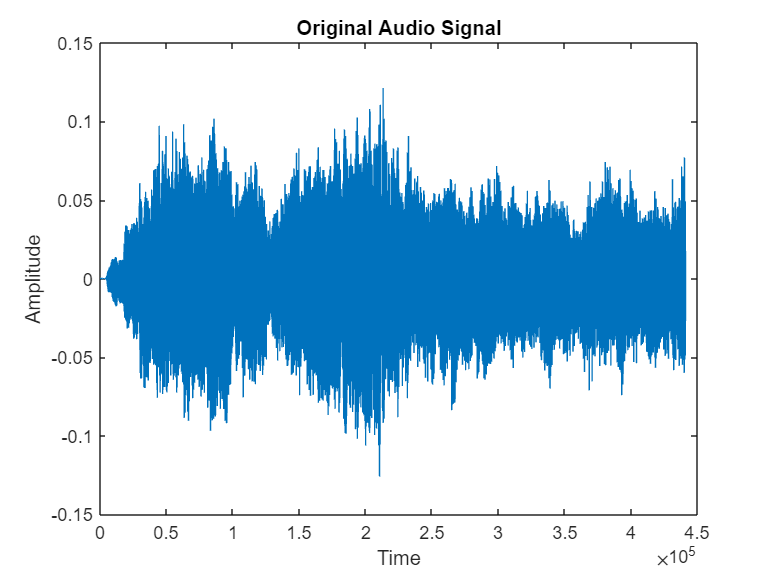

[x, fs] = audioread('Audio01.wav');
sound(x, fs);

figure()
plot(x); title('Original Audio Signal');
xlabel('Time'); ylabel('Amplitude');

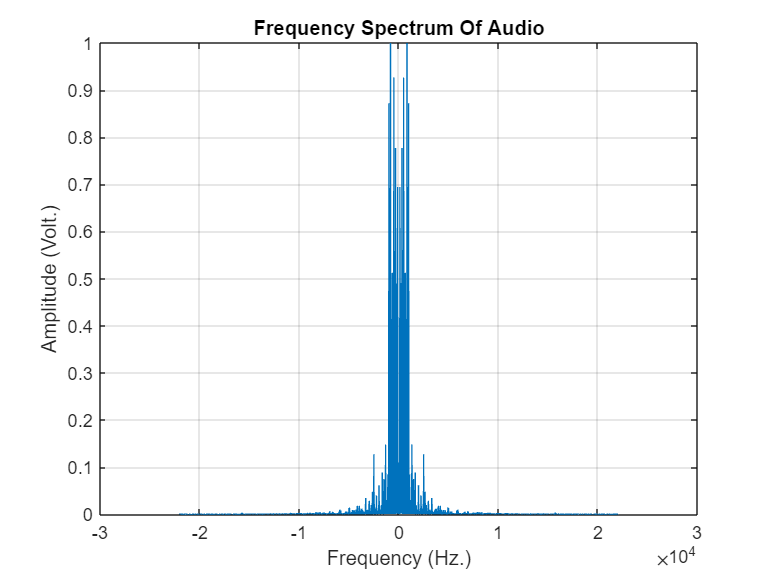


%% Frequency-domain analysis using FFT
N = length(x);                     % Number of samples
X = fft(x);                        % FFT of the signal
X_shifted = fftshift(X);          % Shift zero frequency to center
f = (-N/2:N/2-1)*(fs/N);           % Frequency axis in Hz

% Normalize and plot
X_mag = abs(X_shifted)/ max(abs(X_shifted));  % normalization

figure;
plot(f, X_mag);
title('Frequency Spectrum Of Audio');
xlabel('Frequency (Hz.)');
ylabel('Amplitude (Volt.)');
grid on;

### Section 2-3(b)

Filter is designed by filterDesigner tool and Coefs are available in filter.mat

### Section 2-3(c)

coefs = load('filter.mat')

coefs = struct with fields:
    Num: [6.0941e-04 0.0061 0.0106 0.0054 -0.0056 -0.0057 0.0061 0.0076 -0.0070 -0.0106 0.0080 0.0146 -0.0090 -0.0202 0.0099 0.0279 -0.0106 -0.0395 0.0112 0.0593 -0.0117 -0.1034 0.0120 0.3174 0.4879 0.3174 0.0120 -0.1034 -0.0117 0.0593 0.0112 -0.0395 … ]


h = coefs.Num

h =     0.0006    0.0061    0.0106    0.0054   -0.0056   -0.0057    0.0061    0.0076   -0.0070   -0.0106    0.0080    0.0146   -0.0090   -0.0202    0.0099    0.0279   -0.0106   -0.0395    0.0112    0.0593   -0.0117   -0.1034    0.0120    0.3174    0.4879    0.3174    0.0120   -0.1034   -0.0117    0.0593    0.0112   -0.0395   -0.0106    0.0279    0.0099   -0.0202   -0.0090    0.0146    0.0080   -0.0106   -0.0070    0.0076    0.0061   -0.0057   -0.0056    0.0054    0.0106    0.0061    0.0006


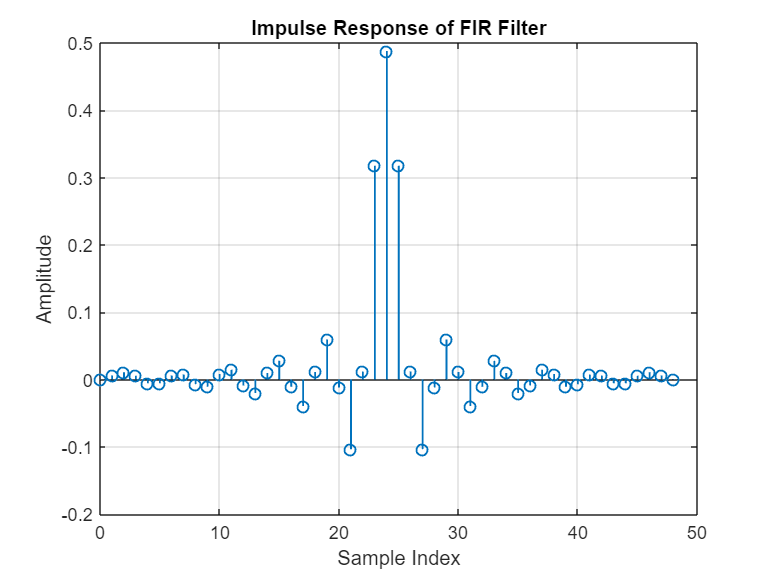


%% Plot Impulse Response (Time Domain)
figure;
stem(0:length(h)-1, h, LineWidth=1);
title('Impulse Response of FIR Filter');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;

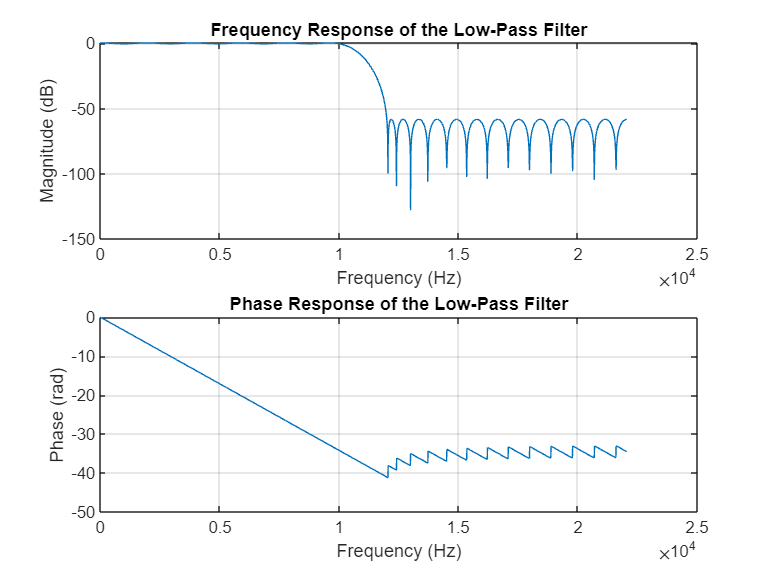




%% Frequency response using freqz
N = 2048;                       % Number of frequency points
[H, f] = freqz(h, 1, N, fs);    % H: complex frequency response, f: frequency axis

%% Plot magnitude response in dB
figure;
subplot(2,1,1);
plot(f, 20*log10(abs(H)));
title('Frequency Response of the Low-Pass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

%% Plot phase response
subplot(2,1,2);
plot(f, unwrap(angle(H)));
title('Phase Response of the Low-Pass Filter');
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
grid on;

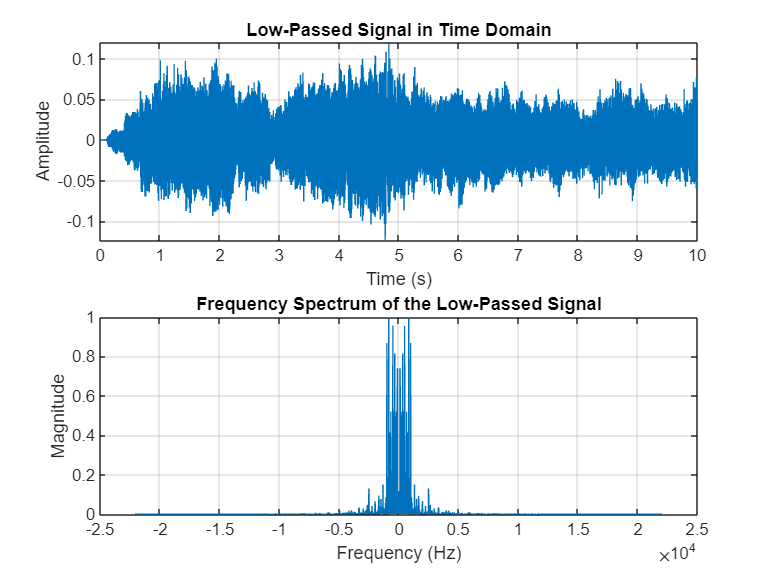


y0 = conv(x, h, 'same');             % Apply low-pass filtering

t = (0:length(y0)-1)/fs;

%% Plot time-domain signal
figure;
subplot(2,1,1);
plot(t, y0);
title('Low-Passed Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%% Compute FFT and plot double-sided frequency spectrum
N = length(y0);
Y_lp = fft(y0);
Y_lp_shifted = fftshift(Y_lp);               % Center zero frequency
f = (-N/2:N/2-1)*(fs/N);                     % Frequency axis in Hz

subplot(2,1,2);
plot(f, abs(Y_lp_shifted)/max(abs(Y_lp_shifted)));
title('Frequency Spectrum of the Low-Passed Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

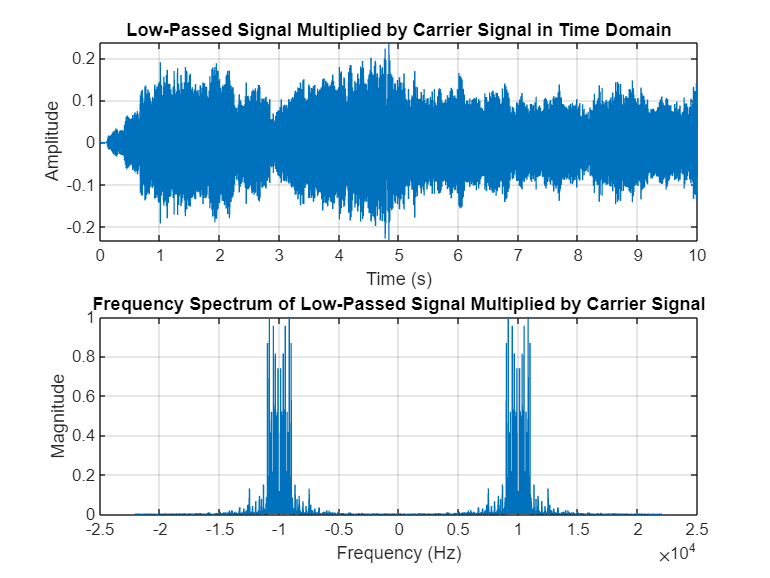



% Modulate the filtered signal using a cosine carrier
f0 = 10000;                          % Carrier frequency (Hz)
n = (0:length(y0)-1)';               % Sample indices
carrier = 2 * cos(2 * pi * f0 / fs * n);
y1 = y0 .* carrier;                  % Modulated signal


%% Plot time-domain signal
figure;
subplot(2,1,1);
plot(t, y1);
title('Low-Passed Signal Multiplied by Carrier Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%% Compute FFT and plot double-sided frequency spectrum
N = length(y1);
Y1_lp = fft(y1);
Y1_lp_shifted = fftshift(Y1_lp);               % Center zero frequency
f = (-N/2:N/2-1)*(fs/N);                     % Frequency axis in Hz

subplot(2,1,2);
plot(f, abs(Y1_lp_shifted)/max(abs(Y1_lp_shifted)));
title('Frequency Spectrum of Low-Passed Signal Multiplied by Carrier Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

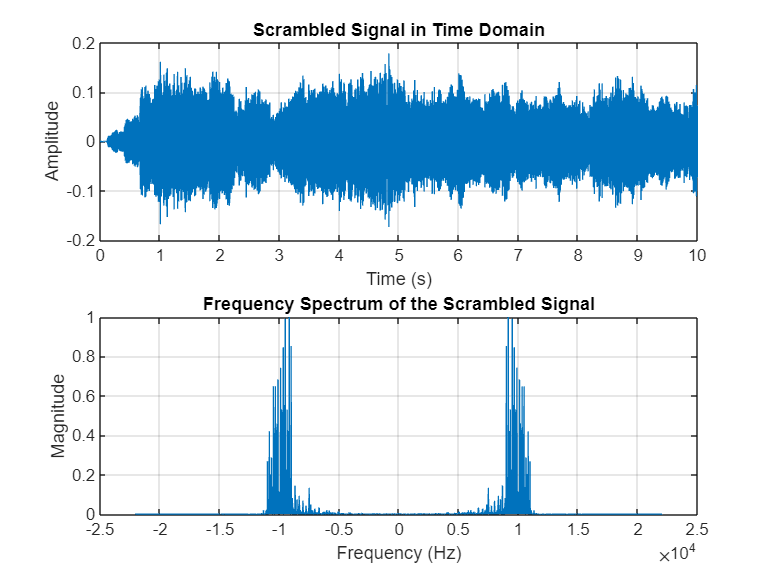




% Apply the same low-pass filter again to remove high frequencies
y2 = conv(y1, h, 'same');            % Final scrambled signal
sound(y2, fs);                       % Play scrambled audio

t = (0:length(y2)-1)/fs;

%% Plot time-domain representation
figure;
subplot(2,1,1);
plot(t, y2);
title('Scrambled Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%% FFT and frequency domain representation (double-sided)
N = length(y2);
Y2_fft = fft(y2);
Y2_shifted = fftshift(Y2_fft);
f = (-N/2:N/2-1)*(fs/N);   % Frequency vector in Hz

subplot(2,1,2);
plot(f, abs(Y2_shifted)/max(abs(Y2_shifted)));
title('Frequency Spectrum of the Scrambled Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### Section 2-3(d)

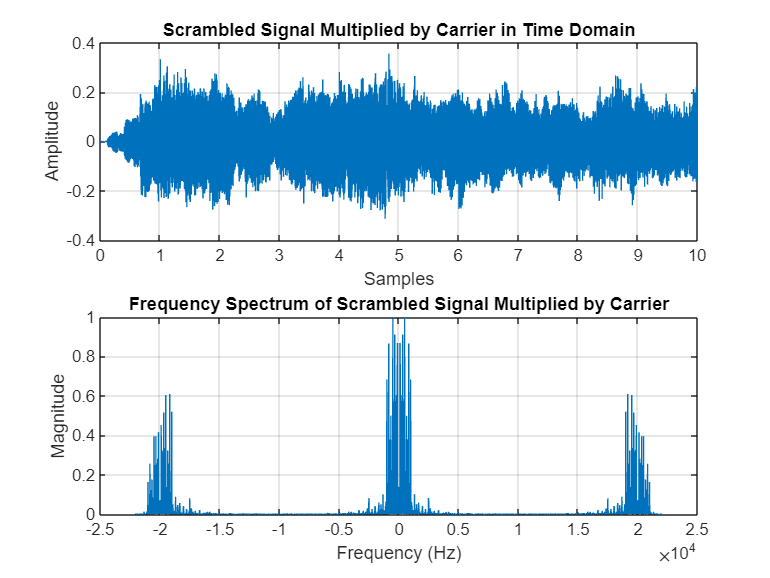


%% 2-3d: Recover the original signal from scrambled signal
y1_recovered = y2 .* carrier;        % Multiply by carrier again

t = (0:length(y1_recovered)-1)/fs;

%% Plot time-domain representation
figure;
subplot(2,1,1);
plot(t, y1_recovered);
title('Scrambled Signal Multiplied by Carrier in Time Domain');
xlabel('Samples');
ylabel('Amplitude');
grid on;

%% FFT and frequency domain representation (double-sided)
N = length(y1_recovered);
Y2_Recovered_fft = fft(y1_recovered);
Y2_Recovered_shifted = fftshift(Y2_Recovered_fft);
f = (-N/2:N/2-1)*(fs/N);   % Frequency vector in Hz

subplot(2,1,2);
plot(f, abs(Y2_Recovered_shifted)/max(abs(Y2_Recovered_shifted)));
title('Frequency Spectrum of Scrambled Signal Multiplied by Carrier');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

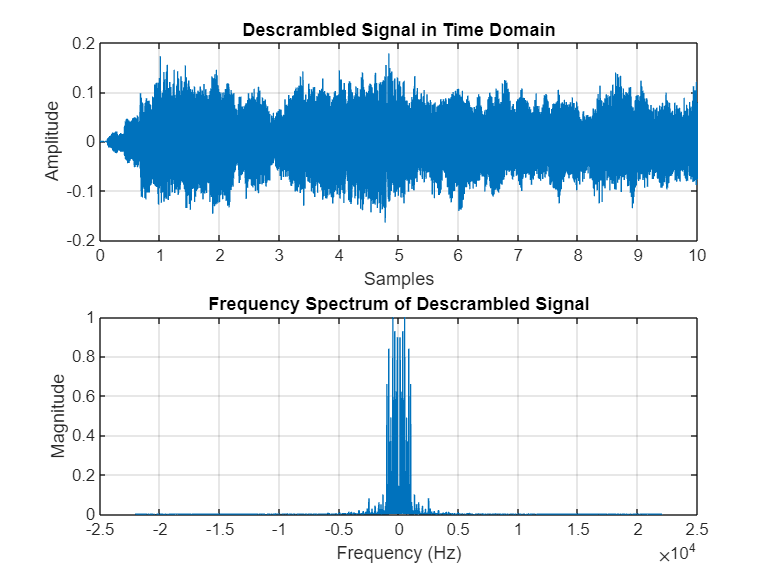


y0_Descrambled = conv(y1_recovered, h, 'same'); % Final filtering
sound(y0_Descrambled, fs);            % Play recovered audio

t = (0:length(y0_Descrambled)-1)/fs;

%% Plot time-domain representation
figure;
subplot(2,1,1);
plot(t, y0_Descrambled);
title('Descrambled Signal in Time Domain');
xlabel('Samples');
ylabel('Amplitude');
grid on;

%% FFT and frequency domain representation (double-sided)
N = length(y0_Descrambled);
Y0_Descrambled_fft = fft(y0_Descrambled);
Y0_Descrambled_shifted = fftshift(Y0_Descrambled_fft);
f = (-N/2:N/2-1)*(fs/N);   % Frequency vector in Hz

subplot(2,1,2);
plot(f, abs(Y0_Descrambled_shifted)/max(abs(Y0_Descrambled_shifted)));
title('Frequency Spectrum of Descrambled Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

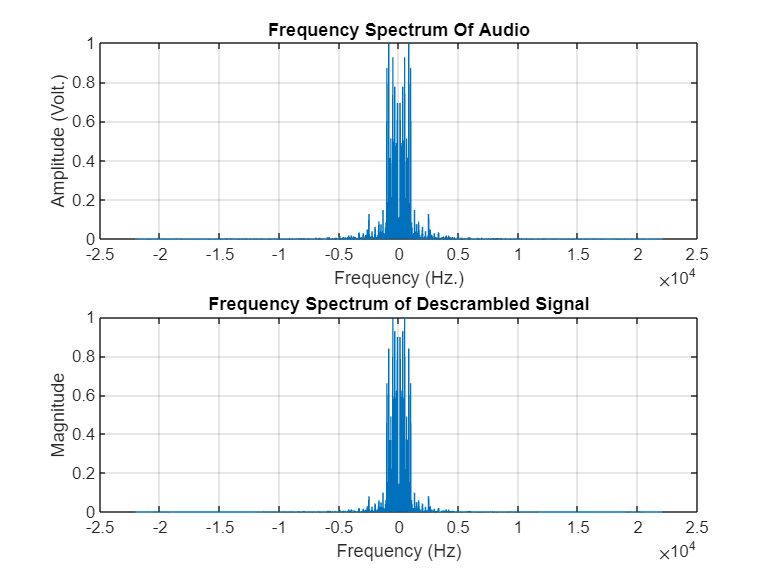


figure()
subplot(2,1,1);
plot(f, X_mag);
title('Frequency Spectrum Of Audio');
xlabel('Frequency (Hz.)');
ylabel('Amplitude (Volt.)');
grid on;
subplot(2,1,2);
plot(f, abs(Y0_Descrambled_shifted)/max(abs(Y0_Descrambled_shifted)));
title('Frequency Spectrum of Descrambled Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

### Adding Gaussian Noise

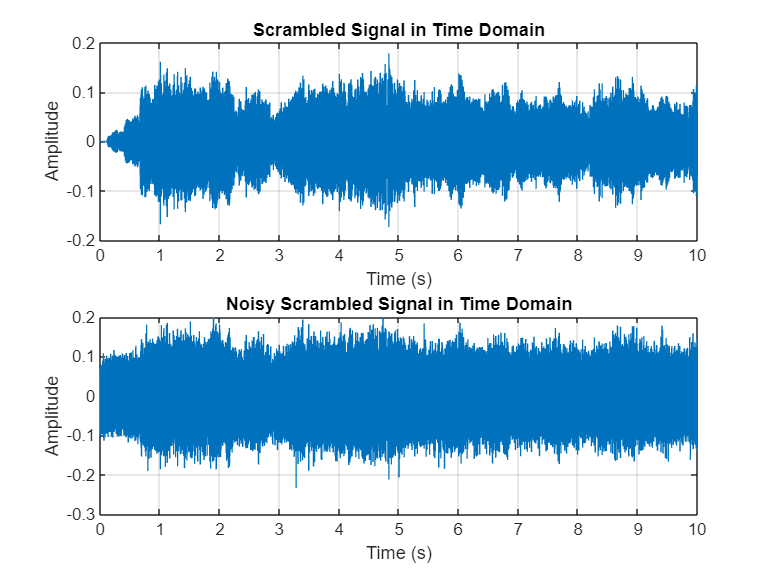

noise_std = 0.03;  % Adjust this to change noise power
noise = noise_std * randn(size(y2));
y2_noisy = y2 + noise;
sound(y2_noisy,fs);

figure;
subplot(2,1,1);
plot(t, y2);
title('Scrambled Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
subplot(2,1,2);
plot(t, y2_noisy);
title('Noisy Scrambled Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

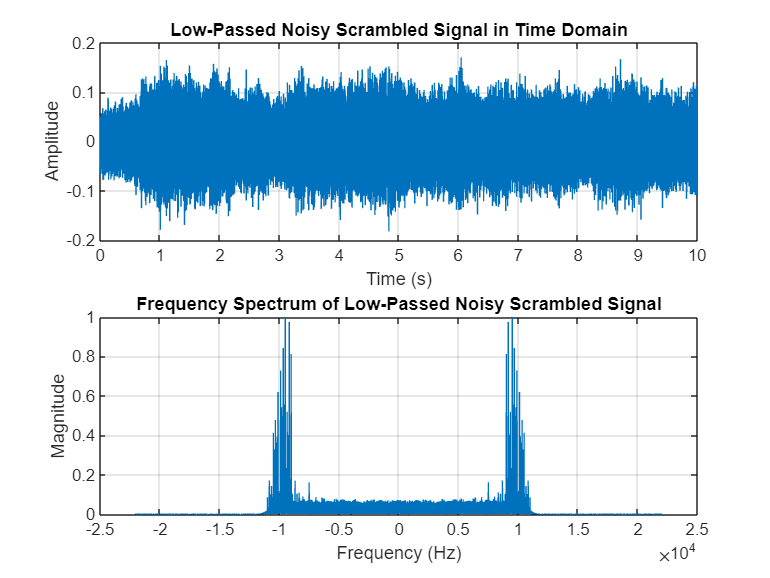


y2_noisy_lp = conv(y2_noisy, h, 'same');

figure;
subplot(2,1,1);
plot(t, y2_noisy_lp);
title('Low-Passed Noisy Scrambled Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%% Compute FFT and plot double-sided frequency spectrum
N = length(y2_noisy_lp);
Y2_Noisy_lp = fft(y2_noisy_lp);
Y2_Noisy_lp_shifted = fftshift(Y2_Noisy_lp);               % Center zero frequency
f = (-N/2:N/2-1)*(fs/N);                     % Frequency axis in Hz

subplot(2,1,2);
plot(f, abs(Y2_Noisy_lp_shifted)/max(abs(Y2_Noisy_lp_shifted)));
title('Frequency Spectrum of Low-Passed Noisy Scrambled Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

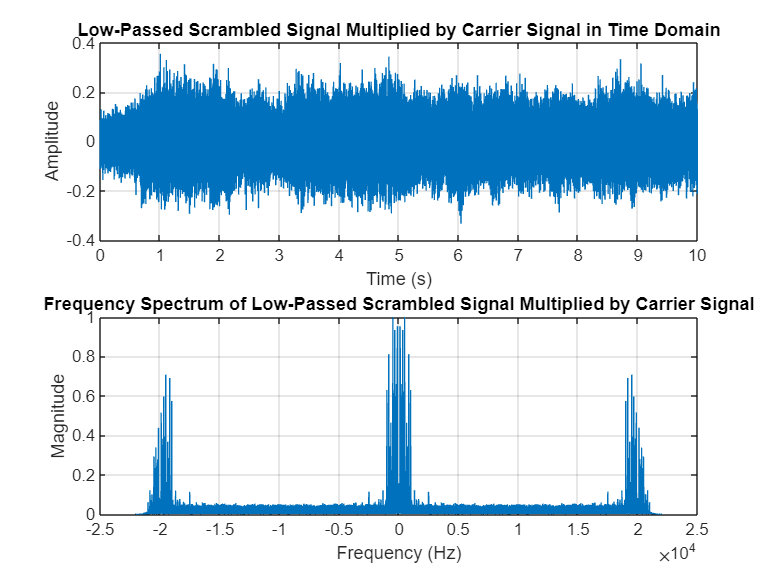


% Modulate the filtered signal using a cosine carrier
f0 = 10000;                          % Carrier frequency (Hz)
n = (0:length(y0)-1)';               % Sample indices
carrier = 2 * cos(2 * pi * f0 / fs * n);
y4 = y2_noisy_lp .* carrier;                  % Modulated signal


%% Plot time-domain signal
figure;
subplot(2,1,1);
plot(t, y4);
title('Low-Passed Scrambled Signal Multiplied by Carrier Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%% Compute FFT and plot double-sided frequency spectrum
N = length(y4);
Y4_lp = fft(y4);
Y4_lp_shifted = fftshift(Y4_lp);               % Center zero frequency
f = (-N/2:N/2-1)*(fs/N);                     % Frequency axis in Hz

subplot(2,1,2);
plot(f, abs(Y4_lp_shifted)/max(abs(Y4_lp_shifted)));
title('Frequency Spectrum of Low-Passed Scrambled Signal Multiplied by Carrier Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

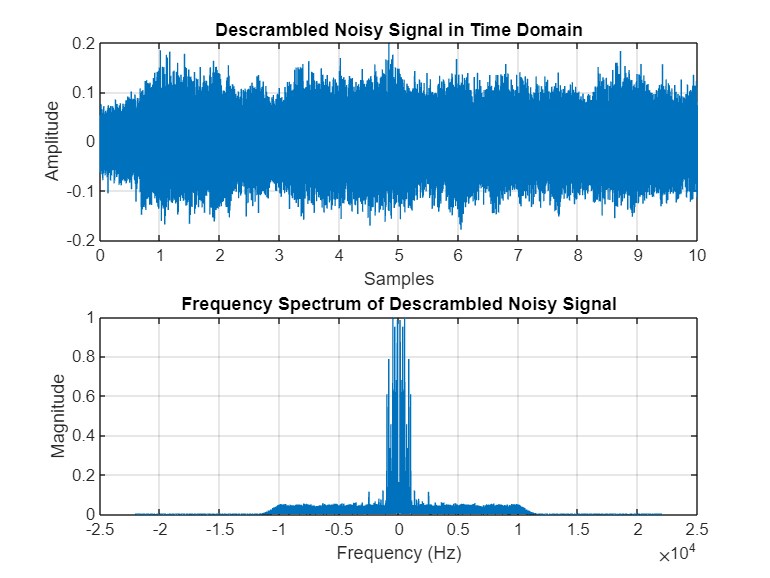


y4_lp = conv(y4, h, 'same');

figure;
subplot(2,1,1);
plot(t, y4_lp);
title('Descrambled Noisy Signal in Time Domain');
xlabel('Samples');
ylabel('Amplitude');
grid on;

%% FFT and frequency domain representation (double-sided)
N = length(y4_lp);
Y4_Descrambled_fft = fft(y4_lp);
Y4_Descrambled_shifted = fftshift(Y4_Descrambled_fft);
f = (-N/2:N/2-1)*(fs/N);   % Frequency vector in Hz

subplot(2,1,2);
plot(f, abs(Y4_Descrambled_shifted)/max(abs(Y4_Descrambled_shifted)));
title('Frequency Spectrum of Descrambled Noisy Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

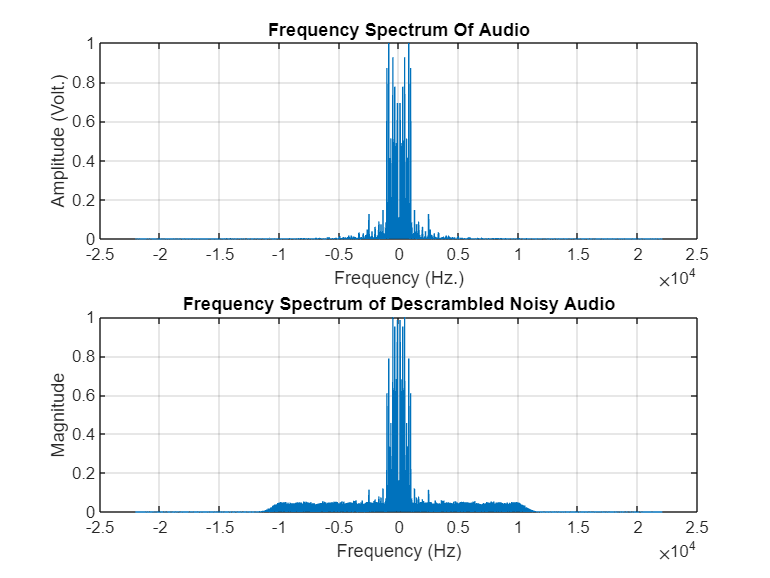


sound(y4_lp,fs);

figure();
subplot(2,1,1);
plot(f, X_mag);
title('Frequency Spectrum Of Audio');
xlabel('Frequency (Hz.)');
ylabel('Amplitude (Volt.)');
grid on;
subplot(2,1,2);
plot(f, abs(Y4_Descrambled_shifted)/max(abs(Y4_Descrambled_shifted)));
title('Frequency Spectrum of Descrambled Noisy Audio');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;



% 1) Compute Mean Squared Error (MSE) and Mean Absolute Error (MAE)
%    between the recovered clean signal and the original signal
mse_clean = mean( (x - y0_Descrambled).^2 );      % MSE(x, y_recovered)
mae_clean = mean( abs(x - y0_Descrambled) );      % MAE(x, y_recovered)

% 2) Compute MSE and MAE between the recovered noisy signal and the original
mse_noisy = mean( (x - y4_lp).^2 ); 
mae_noisy = mean( abs(x - y4_lp) );

% 3) Display results
fprintf('Clean recovery:   MSE = %.6f, MAE = %.6f\n', mse_clean, mae_clean);

Clean recovery:   MSE = 0.000254, MAE = 0.012490


fprintf('Noisy recovery:   MSE = %.6f, MAE = %.6f\n', mse_noisy, mae_noisy);

Noisy recovery:   MSE = 0.000625, MAE = 0.019915


### Section 2-4(a)

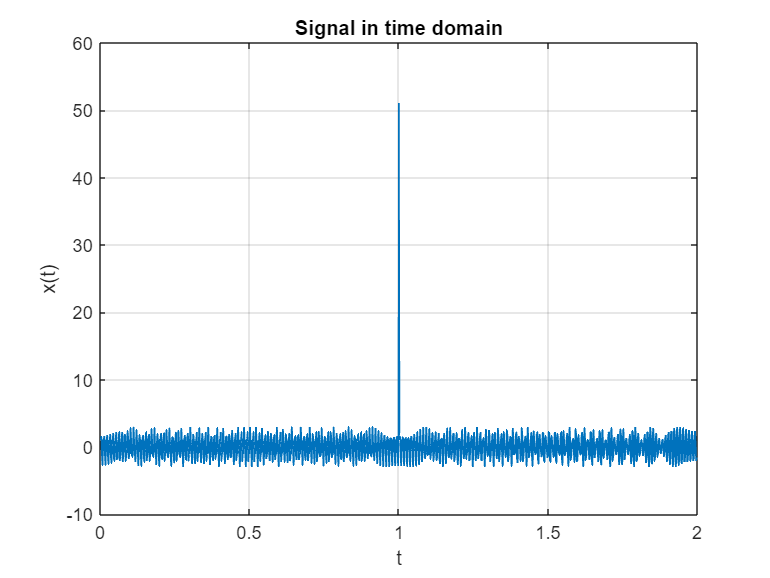

%% Parameters
fs = 500;              % Sampling rate
T = 2;                 % Total duration (seconds)
t = 0:1/fs:T-1/fs;     % Time vector

%% Components
s1 = 2*sin(2*pi*100*t);                    % Fixed 100 Hz tone
s2 = chirp(t, 200, T, 400, 'linear');    % Linear chirp from 200 to 400 Hz
x = s1 + s2;                             % Combined signal

%% Add sharp impulse (like delta function) at t = 1s with amplitude 50
impulse_index = find(t == 1);           % Exact index at 1s
x(impulse_index) = x(impulse_index) + 50;

%% Plot time-domain signal
figure;
plot(t, x, LineWidth=1);
xlabel('t');
ylabel('x(t)');
title('Signal in time domain');
grid on;

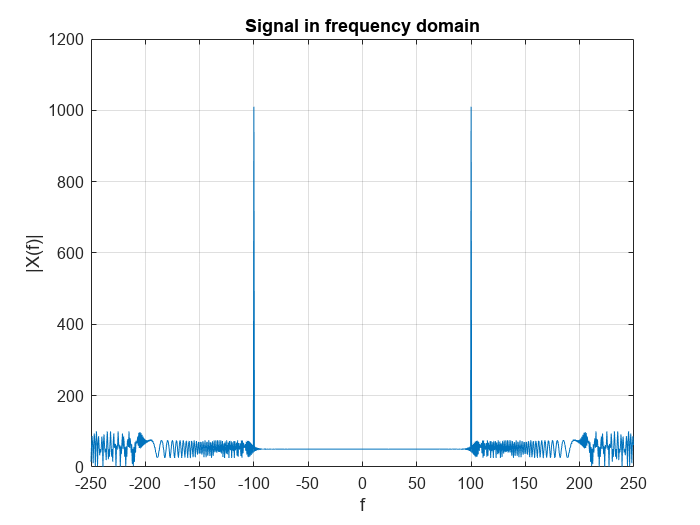



X = fftshift(fft(x));        % Center zero frequency
N = length(x);
f = (-N/2:N/2-1)*(fs/N);     % Frequency vector from -fs/2 to fs/2

%% Plot frequency domain
figure;
plot(f, abs(X));
title('Signal in frequency domain');
xlabel('f');
ylabel('|X(f)|');
grid on;

### Section 2-4(b)

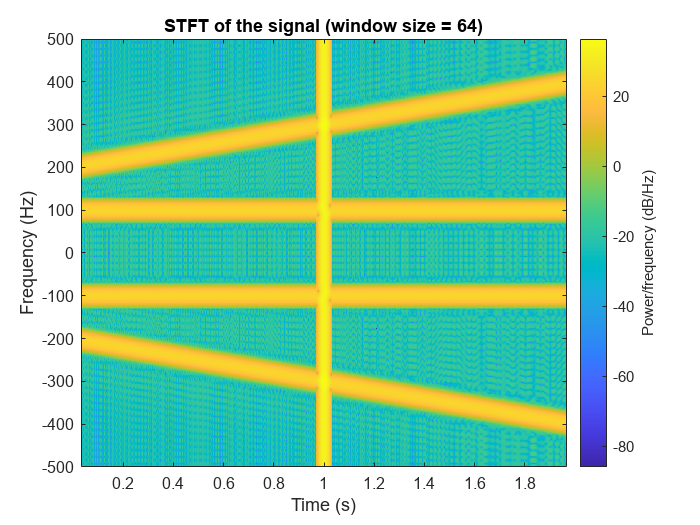

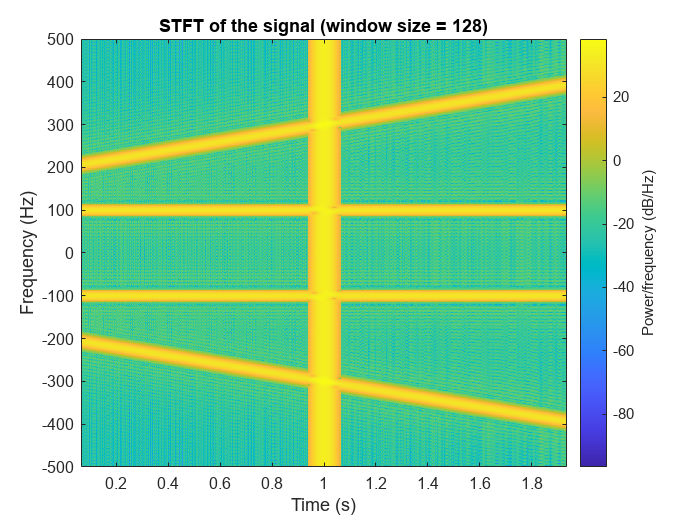

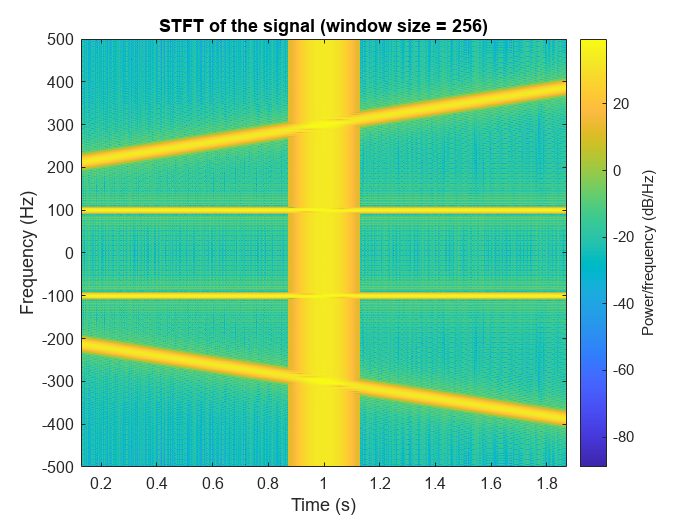

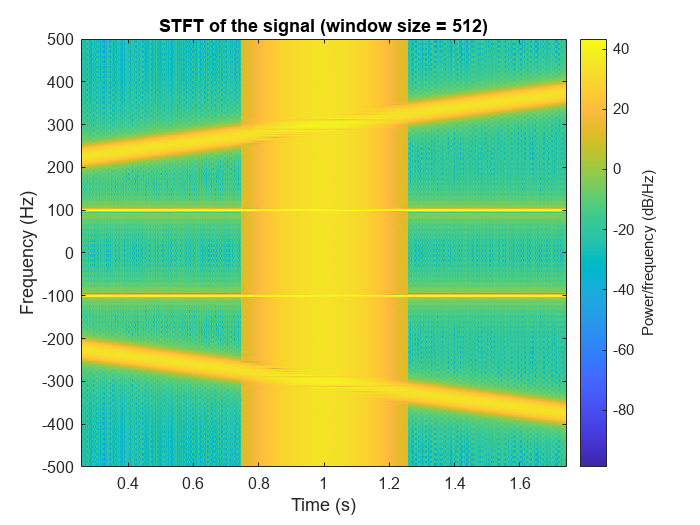

% Define sampling parameters
fs = 1000;                 % Sampling frequency (Hz)
T  = 2;                    % Signal duration (s)
t  = 0:1/fs:T-1/fs;        % Time vector

% Generate the test signal: 100 Hz sine + chirp 200→400 Hz + impulse at 1 s
s1 = sin(2*pi*100*t);                          % 100 Hz sinusoid
s2 = chirp(t, 200, T, 400, 'linear');           % Linear chirp from 200 to 400 Hz
x  = s1 + s2;                                  % Combined signal
[~, idx] = min(abs(t - 1));                    % Find index closest to 1 s
x(idx) = x(idx) + 50;                          % Add impulse of amplitude 50 at t=1 s

% STFT parameters
nfft     = 1024;                               % Number of FFT points
win_list = [64, 128, 256, 512];                % Window lengths to test

% Loop over each window length
for wlen = win_list
    win   = hamming(wlen);                     % Hamming window of length wlen
    nover = wlen - 1;                          % Maximum overlap (wlen-1) for best time resolution

    % Compute centered, double-sided spectrogram
    [S, F, TT] = spectrogram( ...
        x, ...                                 % Input signal
        win, ...                               % Window
        nover, ...                             % Overlap length
        nfft, ...                              % FFT length
        fs, ...                                % Sampling frequency
        'centered' ...                         % Produce frequencies in [-fs/2, +fs/2]
    );

    % Convert to power spectral density in dB/Hz
    P = 10*log10(abs(S).^2);

    % Plot the STFT
    figure;
    imagesc(TT, F, P);                         % Time on x-axis, frequency on y-axis
    axis xy;                                   % Correct axis orientation
    ylim([-500 500]);                          % Limit frequency axis to [-500, 500] Hz

    % Add and label the colorbar
    cb = colorbar('eastoutside');
    ylabel(cb, 'Power/frequency (dB/Hz)');

    % Label axes and title
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('STFT of the signal (window size = %d)', wlen));
end

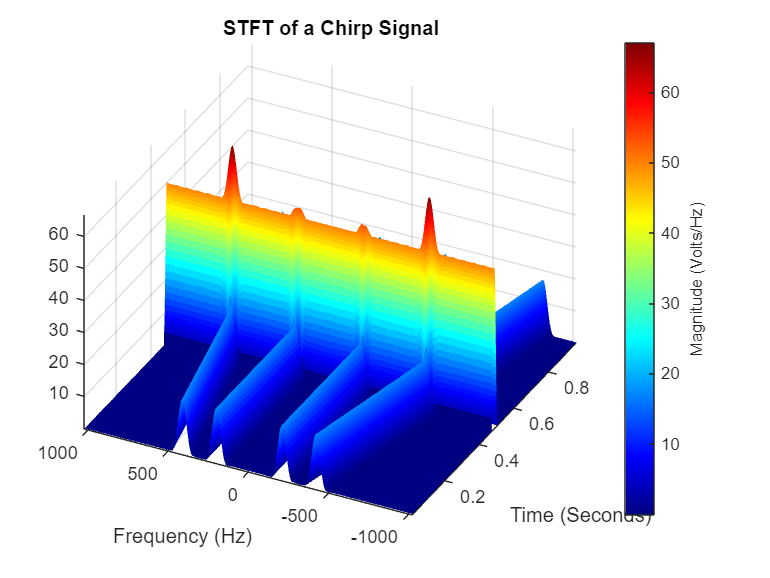



% Complete script to compute and plot a centered STFT of a chirp signal as a 3D surface

% 1. Define sampling parameters
N  = 2^11;                        % Number of time samples
t  = linspace(0, 1, N);          % Time vector from 0 to 1 s
Ts = t(2) - t(1);                 % Sampling interval
fs = 1 / Ts;                      % Sampling frequency

% 3. Compute STFT with a centered, double-sided frequency axis
windowLength   = 64;             % Window length in samples
overlapLength  = windowLength-1;  % Overlap length (maximizes time resolution)
fftLength      = 512;             % Number of FFT points

[S, F, TT] = stft( ...
    x, ...                        % Input signal
    fs, ...                       % Sampling frequency
    Window         = hamming(windowLength), ...
    OverlapLength  = overlapLength, ...
    FFTLength      = fftLength, ...
    FrequencyRange = "centered" ... % Produce frequencies from -fs/2 to +fs/2
);

% 4. Plot the magnitude of the STFT as a 3D surface
figure('Name', 'STFT of a Chirp Signal');
surf(TT, F, abs(S), 'EdgeColor', 'none');  % X=T (time), Y=F (frequency), Z=|S|
axis tight;                              % Remove extra white space
view([-1, -0.5, 1]);                    % Adjust camera view
colormap(jet);                          % Use the 'jet' colormap
cb = colorbar;                          % Add colorbar
ylabel(cb, 'Magnitude (Volts/Hz)');     % Label color axis

% 5. Label axes and title
xlabel('Time (Seconds)');
ylabel('Frequency (Hz)');
title('STFT of a Chirp Signal');

**Discrete Fourier Transform (DFT)**

- Computes a single, global frequency spectrum over the entire signal.

- Provides no information about when specific frequency components occur.

- Well suited for stationary signals whose spectral content does not change in time.

**Short-Time Fourier Transform (STFT)**

- Splits the signal into short, overlapping windows and computes an FFT per window.

- Produces a time–frequency map showing how spectral content evolves.

- Allows analysis of non-stationary signals, trading off time vs. frequency resolution.

**Effect of Window Length on Resolution:**

Short Window (e.g. 64 samples):

  • High time resolution: sudden events (impulses) are accurately localized in time.

  • Low frequency resolution: spectral lines are broad; nearby frequencies may blur.

**Long Window (e.g. 512 samples):**

  • Low time resolution: rapid changes smear over a longer time span.

  • High frequency resolution: spectral lines are sharp and well separated.

### Bonus Question

## 1) Closed-form instantaneous frequency of a linear chirp

Assume the signal is

                                
$$x(t)=e^{j2\pi (f_0t+ \frac{1}{2}Kt^2)} 
$$


then its instantaneous phase is

                                
$$\phi(t) = 2\pi(f_0t+ \frac{1}{2}Kt^2)$$


and the instantaneous frequency is

                                
$$f_{inst}(t) = \frac{1}{2\pi}\frac{d\phi}{dt} = f_0+Kt$$


where

                                
$$K = \frac{f_1-f_0}{T}$$


for a chirp that sweeps from $f_0
$ to $f_1$� in T seconds.

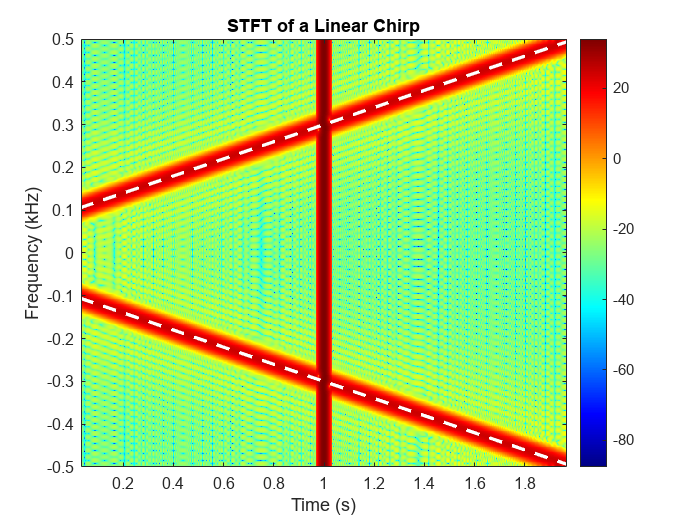


fs = 1000;           % sampling rate
T  = 2;              % duration in seconds
t  = (0:1/fs:T-1/fs)';

% make a linear chirp + impulse
f0 = 100; f1 = 500;  
x  = chirp(t, f0, T, f1);
x(round(fs*1)) = x(round(fs*1)) + 50;

% STFT parameters
windowLength  = 64;
overlapLength = windowLength-1; 
fftLength     = 512;

% compute centered STFT
[S,F,TT] = stft( ...
  x, fs, ...
  'Window',         hamming(windowLength), ...
  'OverlapLength',  overlapLength, ...
  'FFTLength',      fftLength, ...
  'FrequencyRange', 'centered' ...
);

% plot a smooth, dense spectrogram
P = 10*log10(abs(S).^2 + eps);
imagesc(TT, F/1000, P);  % freq in kHz
axis xy;
ylim([-0.5 0.5]);
colorbar;
xlabel('Time (s)');
ylabel('Frequency (kHz)');
title('STFT of a Linear Chirp');

% overlay the theoretical instantaneous frequency
hold on;
K = (f1-f0)/T;
f_inst = f0 + K*TT;      
plot(TT,  f_inst/1000, 'w--','LineWidth',2);
plot(TT, -f_inst/1000, 'w--','LineWidth',2);
hold off;

- **STFT** effectively tracks the instantaneous frequency of a non-stationary signal such as a linear chirp.

- The closed-form line 

                                    
$$f_{inst}(t) = f_0+\frac{f_1-f_0}{T}t$$


- exactly aligns with the high-energy ridge seen in the STFT.

- This agreement confirms that the theoretical instantaneous-frequency model and its MATLAB STFT implementation are fully consistent, both mathematically and in practice.